## Homework 2.4

clear all;
close all;
clc;

Consider the following function:


$$f(x) = e^{ax}-1 = 0
$$


It's clear that $\forall a$ the unique solution is $x=0$

### a. Consider $a=200$. Apply Newton method from $x^{(0)}=1$ with $tol=10^{-3}$ and $tol=10^{-12}$

Let's plot the function with $a=200$

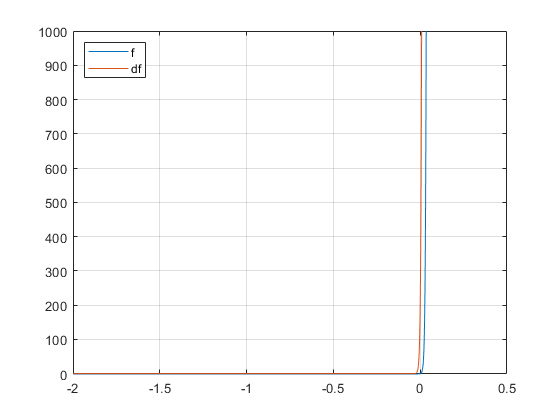

f = @(x, a) exp(x.*a) - 1;
df = @(x, a) a*exp(x.*a);

a = 200;
x = linspace(-2, 2, 10000);

figure();
plot(x, f(x, a));
hold on;
plot(x, df(x, a));
hold off;

ylim([-1,1000]);
grid on;
legend({'f', 'df'}, 'Location', 'northwest');


$$tol=10^{-3}$$


x0 = 1;
tol = 10e-3;
Nmax = 100;

[x, x_iter] = newton(f, df, x0, tol, Nmax, a);

fprintf('x: %g', x);

x: 0.995

display(x_iter);

x_iter =     1.0000    0.9950



error_200_3 = f(x_iter, a);


$$tol=10^{-12}$$


x0 = 1;
tol = 10e-12;
Nmax = 10e3;

[x, x_iter] = newton(f, df, x0, tol, Nmax, a);

fprintf('x: %g', x);

x: -4.82967e-19

display(x_iter);

x_iter =     1.0000    0.9950    0.9900    0.9850    0.9800    0.9750    0.9700    0.9650    0.9600    0.9550    0.9500    0.9450    0.9400    0.9350    0.9300    0.9250    0.9200    0.9150    0.9100    0.9050    0.9000    0.8950    0.8900    0.8850    0.8800    0.8750    0.8700    0.8650    0.8600    0.8550    0.8500    0.8450    0.8400    0.8350    0.8300    0.8250    0.8200    0.8150    0.8100    0.8050    0.8000    0.7950    0.7900    0.7850    0.7800    0.7750    0.7700    0.7650    0.7600    0.7550



error_200_12 = f(x_iter, a);

With $tol=10^{-3}$ we stop very eraly in the computation of the newton method and so we get a solution that is very far from the ideal one. With $tol=10^{-12}$ we need more iterations but we have a more accurate solution, that is about $0$.

### b. Consider $a=10^{-3}$. Apply Newton method from $x^{(0)}=1$ with $tol=10^{-3}$ and $tol=10^{-12}$

Let's plot the function with $a=10^{-3}$

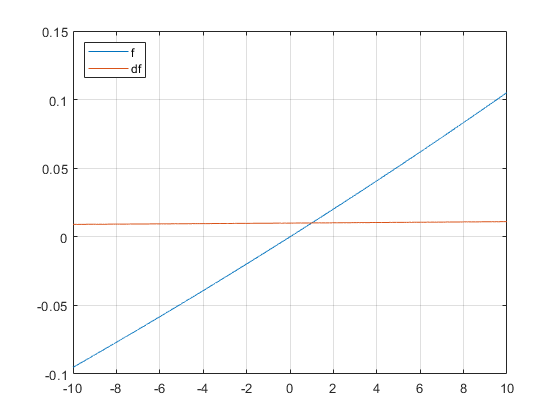

f = @(x, a) exp(x.*a) - 1;
df = @(x, a) a*exp(x.*a);

a = 10e-3;
x = linspace(-10, 10, 10000);

figure();
plot(x, f(x, a));
hold on;
plot(x, df(x, a));
hold off;

grid on;
legend({'f', 'df'}, 'Location', 'northwest');


$$tol=10^{-3}$$


x0 = 1;
tol = 10e-3;
Nmax = 100;

[x, x_iter] = newton(f, df, x0, tol, Nmax, a);

fprintf('x: %g', x);

x: 1.24168e-07

display(x_iter);

x_iter =     1.0000    0.0050    0.0000



error_3_3 = f(x_iter, a);


$$tol=10^{-12}$$


x0 = 1;
tol = 10e-12;
Nmax = 10e3;

[x, x_iter] = newton(f, df, x0, tol, Nmax, a);

fprintf('x: %g', x);

x: 9.0618e-16

display(x_iter);

x_iter =     1.0000    0.0050    0.0000    0.0000    0.0000



error_3_12 = f(x_iter, a);

With $tol=10^{-3}$ we stop very eraly in the computation of the newton method but, with respect to the previous case, we get anyway a good approximation for the zero. With $tol = 10^{-12}$ the estimate is even more accurate.

### c. For both items compare the absolute value of the residual with the error

Error with $a=200$

error_200_3

error_200_3 = 	1.0e+86 *

    7.2260    2.6583


error_200_12

error_200_12 = 	1.0e+86 *

    7.2260    2.6583    0.9779    0.3598    0.1323    0.0487    0.0179    0.0066    0.0024    0.0009    0.0003    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% figure();
% plot(error_200_3, 'LineWidth', 2);
% hold on;
% plot(error_200_12, 'LineWidth', 2);
% hold off;
% 
% grid on;
% 
% title("Newton method residual error with a = 200");
% legend({'10e-3', '10e-12'}, 'Location', 'northeast');

Error with $a=10^{-3}$

error_3_3

error_3_3 =     0.0101    0.0000    0.0000


error_3_12

error_3_12 =     0.0101    0.0000    0.0000         0         0



% figure();
% plot(error_3_3, 'LineWidth', 2);
% hold on;
% plot(error_3_12, 'LineWidth', 2);
% hold off;
% 
% grid on;
% 
% title("Newton method residual error with a = 10e-3");
% legend({'10e-3', '10e-12'}, 'Location', 'northeast');

The Newton method is based on the incremental error, but the case with $a=200$ is a typical case in which the incremental error is uncorrelated with the residual error, since a small increment in $x$ means an huge variation in the value of $y$, so with a tolerance of $10^{-3}$ we reach quickly a good incremental error $x^k - x^{k-1}$ that is completely uncorrelated with an huge incremental error $f(x^k) - f(0)$.

### Functions

function [x, x_iter] = newton(f, df, x0, tol, Nmax, a)
    % Nmax since we don't know a priori if with the passed
    % tol we will reach a convergence

    x_iter(1) = x0;
    
    for k = 2:Nmax
        
        % Check if the derivative is zero or simil-zero
        if abs(df(x_iter(k-1), a)) < 1e-8
            break;
        end
        
        x_iter(k) = x_iter(k-1) - (f(x_iter(k-1), a) / df(x_iter(k-1), a));
    
        if abs(x_iter(k) - x_iter(k-1)) < tol
            break;
        end
    end
    
    x = x_iter(end);
end